# **Spring Pendulum Project**

#### Team # 02

#### Team Members:

Jacob Juers

Dennis Pomazanov

Christopher Barnes

## **Problem Statement**

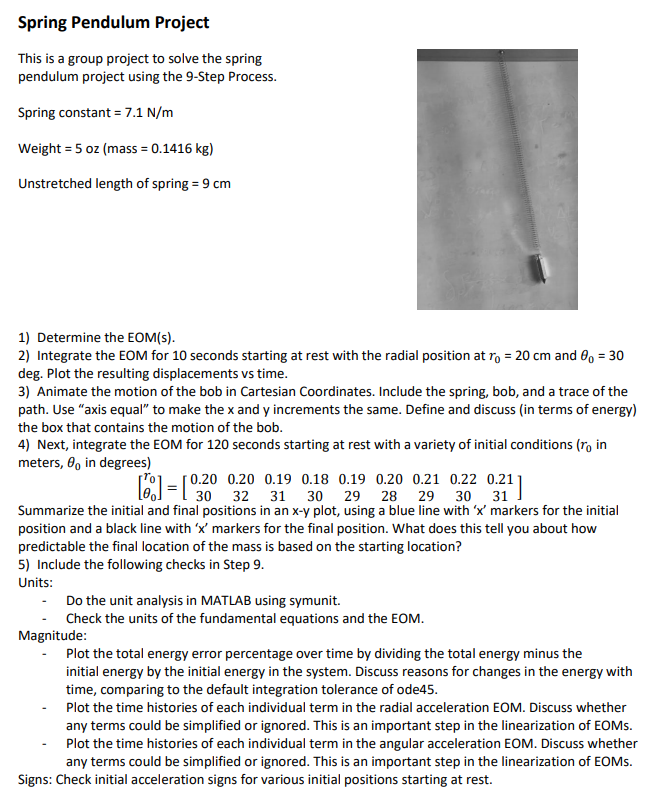

## **Step 1: Conceptualize the Problem**

Find equations of motion and use them to solve.

- Assume pendulum dynamics combined with linear spring dynamics

- 2 degrees of freedom

- Spring stretches linearly in the radial direction

- Bob moves in both the radial and tangential directions simotaneously (does not have a circular path)

clear
clc
clf

## Step 2: Coordinate System

Align the radial direction parallel with the pendulum rod and spring. Align the tangetial direcion normal to the radial direction.

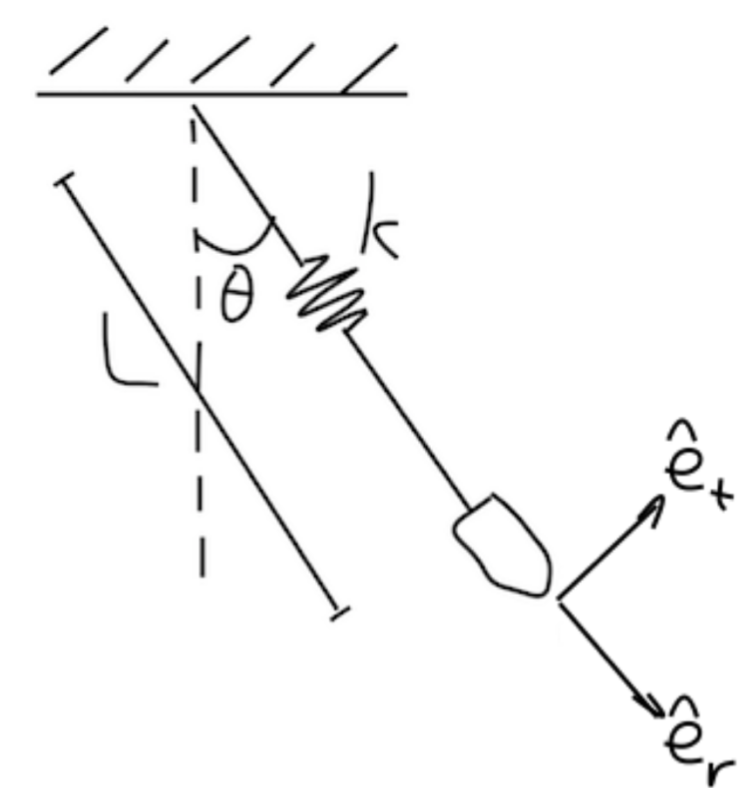

## Step 3: Free-Body Diagram

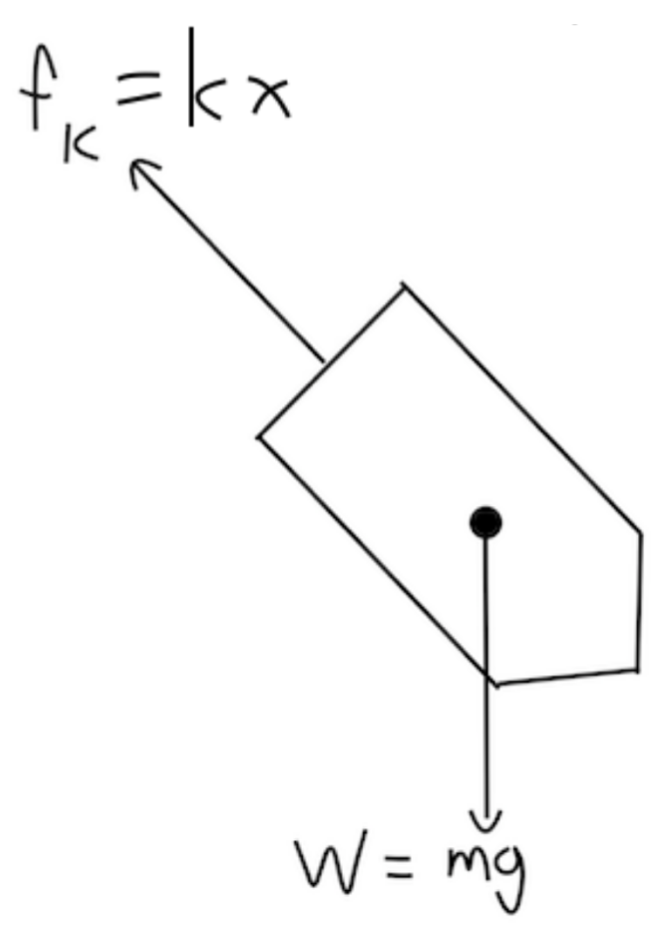

The radial transverse coordinate frame was chosen due to the the motion of the spring mass pendulum. There are two degrees of freedom for the mass, in the radial or $\hat{e}_r$ direction and the transverse or $\hat{e}_t$. The right and top sides were chosen as positive as those directions are typical positive direction.

## Step 4: **Fundamental Equations**

Using the equation sheet:


$$\bar{a} =\left(\ddot{r} -r\dot{\theta^2 } \right)\hat{e_r } +\left(\ddot{r\theta } +2\dot{r} \theta^˙ \right)\hat{e_t }$$



$$\sum F = m\bar{a$$


syms m L r r_dot r_ddot theta theta_dot theta_ddot k g x


$$\sum{F_r} = m(\ddot{r}-r\dot{\theta}^2) = mgCos(\theta)-f_k$$


eqn(1) = m*(r_ddot - (r*(theta_dot)^2)) == m*g*cos(theta) - k*(r-L)

$$eqn = m\,\left(\ddot{r}-r\,{\dot{\theta }}^{2}\right)=k\,\left(L-r\right)+g\,m\,\cos\left(\theta \right)$$


$$\sum{F_t} = m(r\ddot{\theta}+2\dot{r}\dot{\theta})  = -mgSin(\theta)$$


eqn(2) = m*(r*theta_ddot + (2*r_dot*theta_dot)) == -m*g*sin(theta)

$$eqn = \left(\begin{array}{cc} m\,\left(\ddot{r}-r\,{\dot{\theta }}^{2}\right)=k\,\left(L-r\right)+g\,m\,\cos\left(\theta \right) & m\,\left(r\,\ddot{\theta }+2\,\dot{r}\,\dot{\theta }\right)=-g\,m\,\sin\left(\theta \right) \end{array}\right)$$

## Step 5: Knowns and Unkowns

**Knowns:**

$m$ ( mass 0.1416 kg)

$g$ (acceleration due to gravity 9.81 $\frac{m}{s^2 }$)

k  ( spring constant 7.1$\frac{N}{m}$)

$\theta$ (angle of the pendulum from vertical)

$\dot\theta$ (angular velocity)

L (unstreched length 0.09 m)

r (total length)

$\dot{r}$ (tangential velocity)

**Unkowns:**

$\ddot\theta$ (acceleration in the tangential direction)

$\ddot{L}$ (acceleration in the radial direction)

**Two Unkowns, Two equations**

## Step 6: Constraints 

No constraints needed for this problem. There are already two equations and two unknowns so we can solve right away.

## Step 7: Equations of Motion

unknowns = solve(eqn,[theta_ddot,r_ddot]);
theta_ddot = simplify(unknowns.theta_ddot)

$$theta\_ddot = -\frac{2\,\dot{r}\,\dot{\theta }+g\,\sin\left(\theta \right)}{r}$$

r_ddot = simplify(unknowns.r_ddot)

$$r\_ddot = \frac{m\,r\,{\dot{\theta }}^{2}+L\,k-k\,r+g\,m\,\cos\left(\theta \right)}{m}$$

## Step 8: Solve the Problem

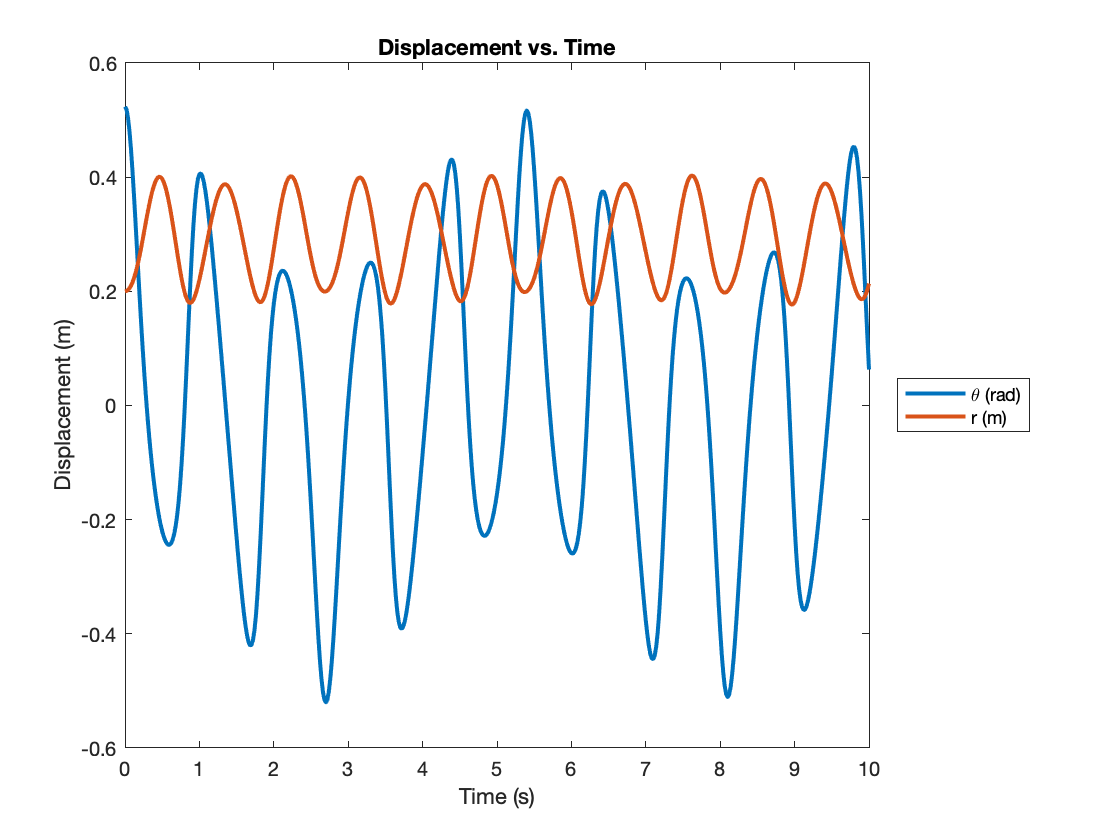

syms theta(t) theta_dot(t) r(t) r_dot(t)

accelEOMs = subs([theta_ddot;r_ddot],...
    [str2sym('theta'),str2sym('r'),str2sym('theta_dot'),str2sym('r_dot')],...
    [theta,r,theta_dot,r_dot]);
eom = odeFunction([theta_dot;r_dot;accelEOMs],[theta;r;theta_dot;r_dot],g,m,L,k);

kn = 7.1;
mn = 0.1416;
Ln = 0.09;
gn = 9.81;
IC(1) = 30*pi/180; % initial theta
IC(2) = 0.2; % inital r
IC(3) = 0; % initial theta-dot
IC(4) = 0; % initial r-dot
t0 = 0; % initial time
tf = 10; % final time
ntime = 501; % number of time points
[T,S] = ode45(@(t,s)eom(t,s,gn,mn,Ln,kn),linspace(t0,tf,ntime),IC);
plot(T,S(:,1:2),'-','linewidth',2)
title('Displacement vs. Time')
xlabel('Time (s)')
ylabel('Displacement (m)')
legend('\theta (rad)','r (m)','Location',"eastoutside")

### Animation

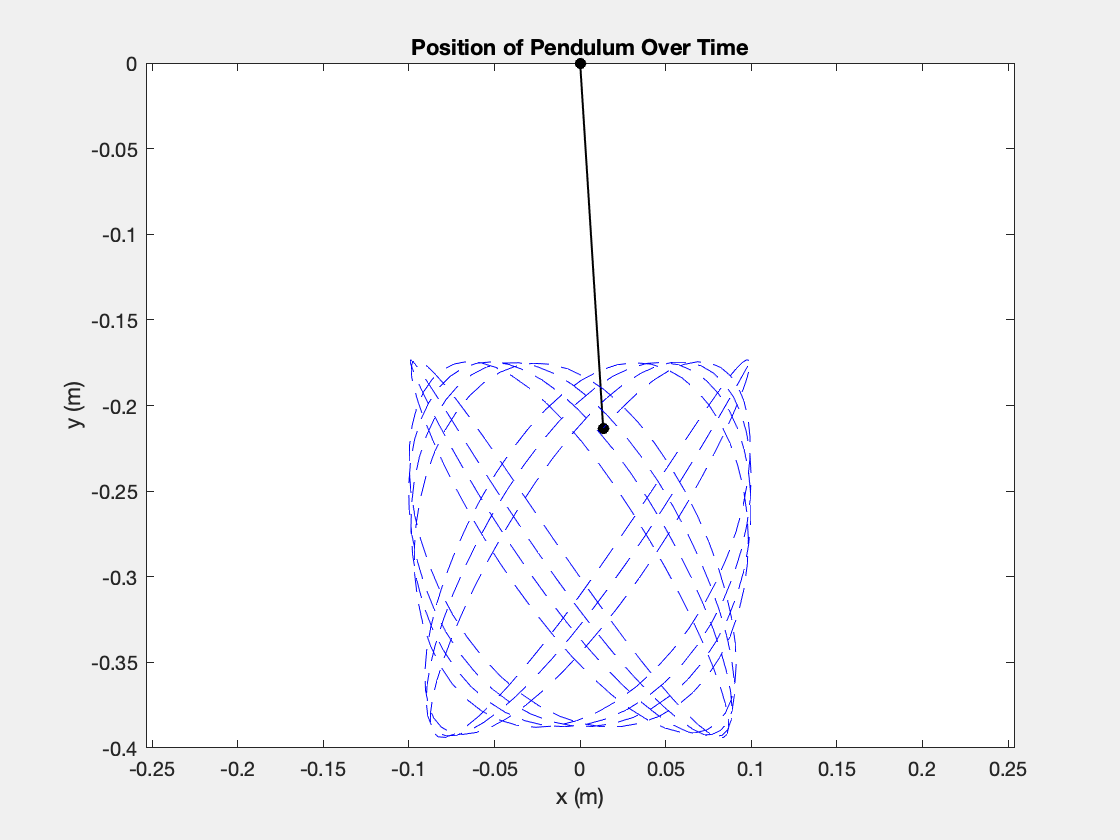

ax = S(:,2).*sin(S(:,1));
ay = S(:,2).*-cos(S(:,1));
figure("Visible","on")
h = plot([0,ax(1)],[0,ay(1)],'-ko','LineWidth',1,'MarkerSize',5,'MarkerFaceColor','k');
hold on
h1 = plot(ax(1),ay(1),'--b');
title('Position of Pendulum Over Time')
xlabel('x (m)')
ylabel('y (m)')
% axis([-0.15 0.15 -0.4 0]);
% axis equal
for i = 2:length(T)
    set(h(1),'XData',[0,ax(i)],'YData',[0,ay(i)]);
    set(h1,'XData',ax(1:i),'YData',ay(1:i));
    drawnow
    axis([-0.15 0.15 -0.4 0]);
    axis equal
end

Ingration over 120 seconds

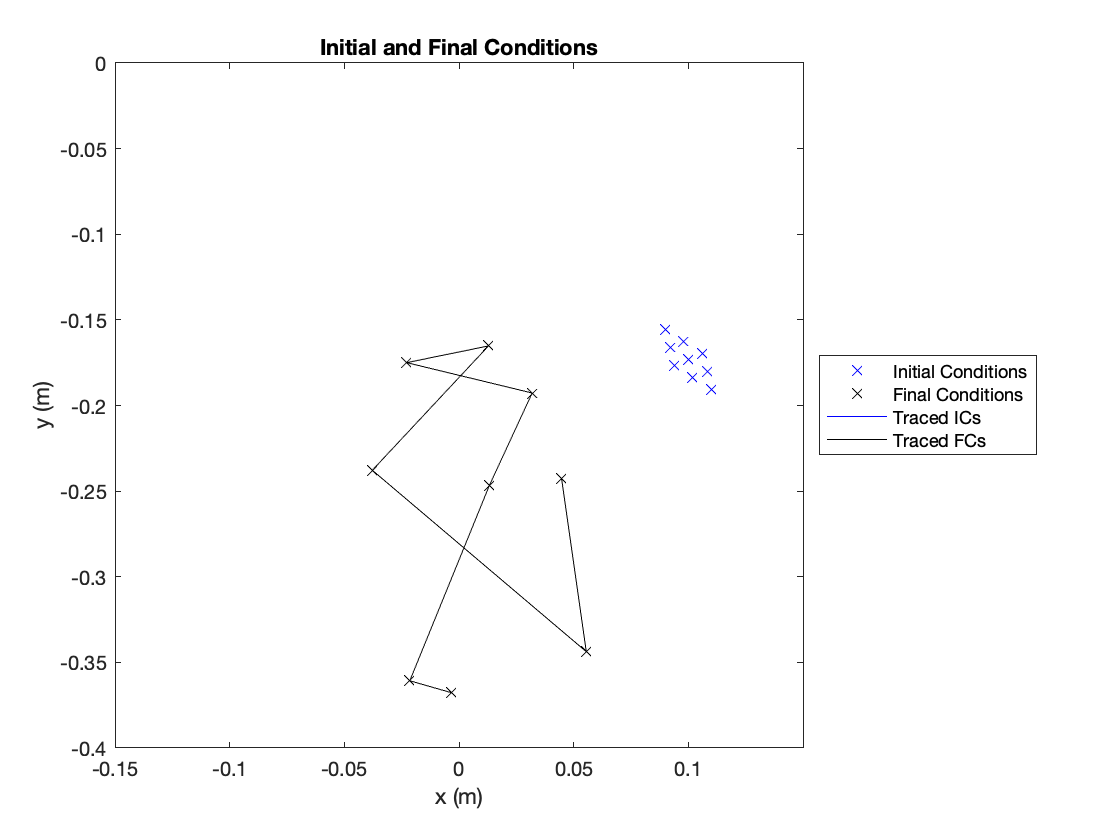

rn = [0.20 0.20 0.19 0.18 0.19 0.20 0.21 0.22 0.21];
theta0 = [deg2rad(30), deg2rad(32), deg2rad(31),deg2rad(30), deg2rad(29), deg2rad(28), deg2rad(29), deg2rad(30), deg2rad(31)];
for i = 1:9
    [~,S2(:,4*i-3:4*i)] = ode45(@(t,s)eom(t,s,gn,mn,Ln,kn),linspace(0,120,12001),[theta0(i),rn(i),0,0]);
end
for ii= 1:9
    X(:,ii) = S2(:,4*ii-2).*sin(S2(:,ii*4-3));
    Y(:,ii) = S2(:,4*ii-2).*-cos(S2(:,ii*4-3));
end
figure;
for iii = 1:9
    plot(X(1,iii),Y(1,iii),'bx');
    hold on;
    plot(X(end,iii),Y(end,iii),'kx');
    axis([-0.15 0.15 -0.4 0]);
    title('Initial and Final Conditions')
    xlabel('x (m)')
    ylabel('y (m)')
    hold on
    plot(X(end,1:9),Y(end,1:9),'b-');
    hold on
    plot(X(end,1:end),Y(end,1:end),'k-');
    legend('Initial Conditions','Final Conditions','Traced ICs','Traced FCs','Location',"eastoutside")
end

The box containing the motion of the bob represents the combined energy as kinetic energy, and as potential energy. For instance, if the box was larger this would indicate that there is more total energy within the system becasue more energy would be required for a larger displacement in the x and y directions. The same but opposite is true for a smaller box. By looking at the markers for the initial(blue) positions and final(black) positions you can see that the final positions are not very easy to predict based on the starting locations. Looking at the graph above, the final positions seem to be much more random than the initial "diamond-like" pattern.

## Step 9: Does It Make Sense?

## Units:

Check Equations using symunit


$$m\ g\  k\ \text{(Contants/Givens)}\  \theta\ \dot\theta\  r\ \dot r\ \text{(State Variables)}$$


u = symunit;
Variables.m = m*u.kg;
Variables.x = x*u.m;
Variables.g = g*u.m/u.s^2;
Variables.k = k*u.N/u.m;
Variables.r = r*u.m;
Variables.L = L*u.m;
Variables.r_dot = r_dot*u.m/u.s;
Variables.r_ddot = r_ddot*u.m/u.s^2;
Variables.theta_dot = theta_dot/u.s;
Variables.theta_ddot = theta_ddot/u.s^2;
eqnUnits = subs(eqn,Variables);
checkUnits(eqnUnits)

ans = struct with fields:
    Consistent: [1 1]
    Compatible: [1 1]


Check EOMs

thetaddot_Units = subs(theta_ddot,Variables);
[~,theta_Units] = separateUnits(thetaddot_Units);
theta_Units

$$theta\_Units = \frac{1}{s^{2}}$$

Confirms that $\ddot\theta$ is in rad/$s^2$

rddot_Units = subs(r_ddot,Variables);
[~,r_Units] = separateUnits(rddot_Units);
r_Units

$$r\_Units = 1\,\frac{N}{\mathrm{kg}}$$

## Magnitude

The plots below summarize the significance of the magnitudes discussed as well as the correctness of the magnitudes.

### Plot the total energy error percentage over time


$$E = KE+PE_{gravity} +PE_{spring}= \frac{1}{2}mv^2+mgh+\frac{1}{2}kx^2 \\
E = \frac{1}{2}m\left(\dot{r}\right)^2+\frac{1}{2}m\left(r\dot{\theta}\right)^2+mg\left(-r\,cos(\theta) \right) + \frac{1}{2}k(r-L)^2$$


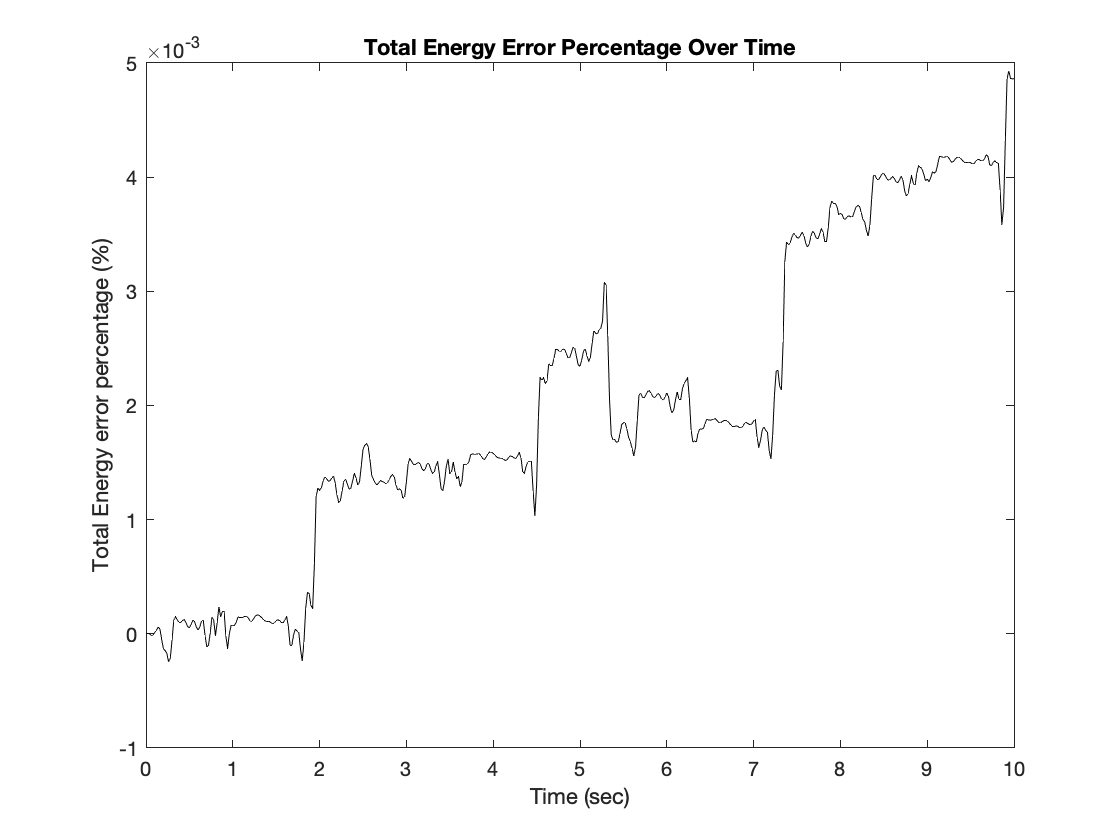

Etot = 0.5.*mn.*(S(:,4)).^2+0.5.*mn.*(S(:,2).*S(:,3)).^2+mn.*gn.*(-S(:,2).*cos(S(:,1)))+0.5.*kn.*(S(:,2)-Ln).^2;
E0 = mn*gn*-0.20*cos(30*pi/180)+0.5*kn*(0.20-0.09)^2;
Eerror = (Etot-E0)./E0;
figure
T2 = linspace(0,10,501);
plot(T2,Eerror,'-k')
title('Total Energy Error Percentage Over Time')
xlabel('Time (sec)')
ylabel('Total Energy error percentage (%)')

The reason that energy changes with time is because of the integration tolerance of ode45. Since ode45 is a nonstiff ODE solver, this means that it does not have tolerances as tight as other solvers. So, as ode45 integrates, it becomes less accurate which causes the error to increase. The reason that we use ode45 is that it is fairly efficient and fast at solving nonstiff problems and it works well for most applications. The reason for this is that it does less work per step than a stiff ODE solver.

### Plot the time histories of each individual term in the radial acceleration EOM

No terms should be simplified or ignored. The graph below represents the terms of radial acceleration. By looking at the plot, you can see that the secind and third terms do not have much of an oscillatory motion, they are more jumpy. The first term however has a somewhat varying sinosoidal pattern. This most likely represents the acceleration resulting from the spring force on the pendulum bob.


$$\ddot r = \frac{mr\dot\theta^2+Lk-kr+gmcos(\theta)}{m}$$


Terms: $r\dot\theta^2$,$\frac{-k(r-L)}{m}$,$gcos(\theta)$

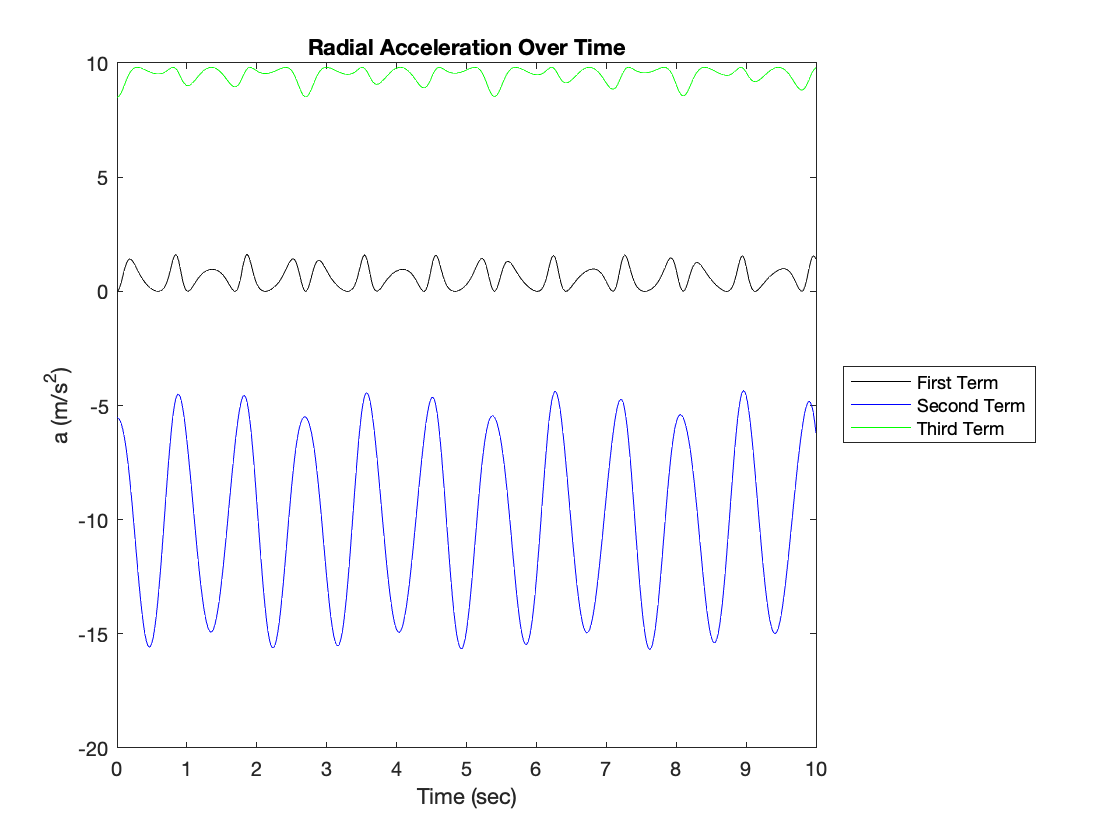

figure
plot(T,(S(:,2)).*(S(:,3).^2),'-k')
title('Radial Acceleration Over Time')
xlabel('Time (sec)')
ylabel('a (m/s^2)')
hold on;
tn = linspace(0,10,11);
plot(T,-kn.*S(:,2)./mn + kn*Ln/mn ,'-b')
hold on;
plot(T,gn.*cos(S(:,1)),'-g')
legend('First Term','Second Term','Third Term','Location','eastoutside')

### Plot the time histories of each individual term in the angular acceleration EOM

No terms should be simplified or ignored. The plot below represents the accelerations in the angular direction. As you can see in terms and the plot below, there is no contribution to acceleration from the spring in the radial direction. The terms present are only a result of the weight components in the angular direction over time. As a result, the acceleration will be zero when the pendulum is vertical because there is no contribution in the tangential direction.


$$\ddot\theta=-\frac{2\dot r\dot\theta+gsin(\theta)}{r}$$


Terms: $\frac{-2\dot r\dot\theta}{r}$, $\frac{gsin(\theta)}{r}$

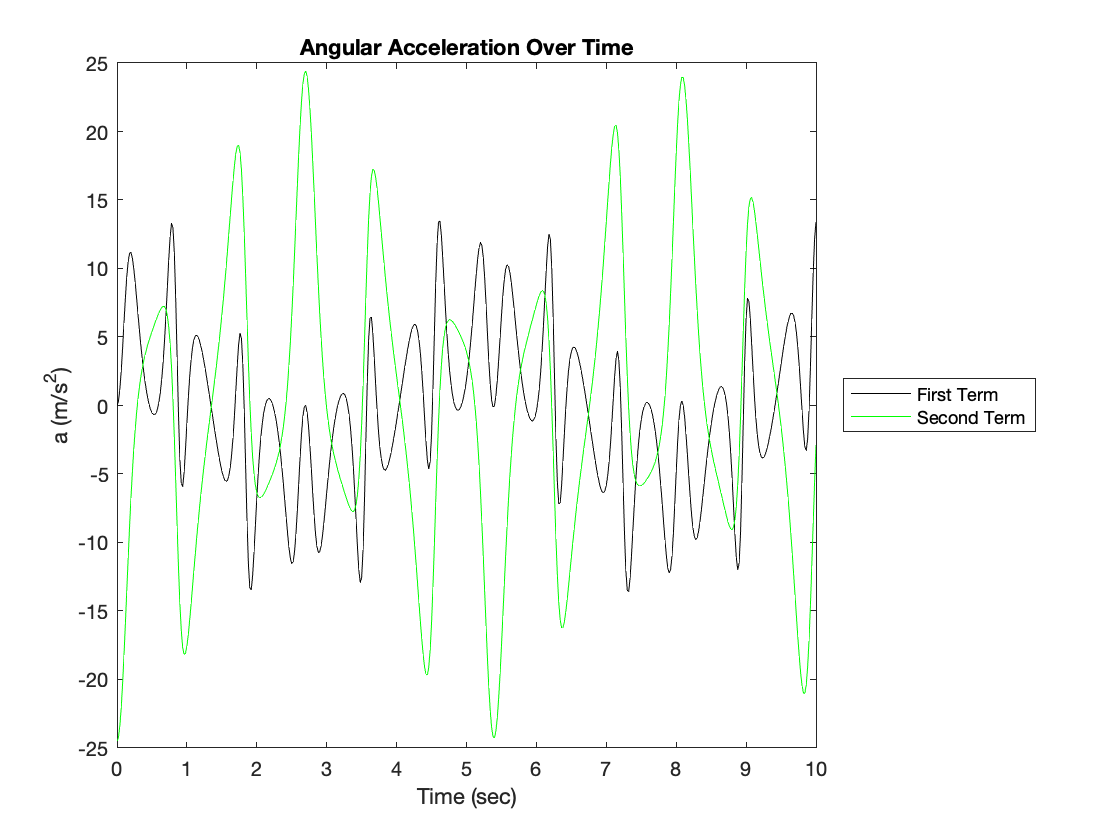

figure
plot(T,-2.*S(:,4).*S(:,3)./(S(:,2)),'-k')
title('Angular Acceleration Over Time')
xlabel('Time (sec)')
ylabel('a (m/s^2)')
hold on;
plot(T,-gn.*sin(S(:,1))./(S(:,2)),'-g')
legend('First Term','Second Term','Location','eastoutside')

## Signs

The initial radial acceleration coming from rest is postitive as it should be since the spring starts out streched. The initial angular acceleration is negitive as it should be since the pendulum starts out at positive initial angles of $\theta$ so the mass would be accelerating to the left to try to reach equilibrium in the angular direction. Overall, when looking at the plots involved in this probelm, the signs look correct and make sense.

## Appendix

### Contributions

Jacob: EOM's, EOM Function, symbolic solution, plotting initial and final positions, step 9, explanations, animation

Dennis: EOM's, EOM Function, animation, symbolic solution, all plotting, symunit, ode45, step 9, analytical solution

Christopher: EOM's, EOM Function, animation, symbolic solution, all plotting, symunit, ode45, step 9, analytical solution

We all participated in all 9 steps of the process. As group members were working, the other group member(s) worked on the same tasks and checked each others work.

### Attachments